# Plots trajectories of 2D linear systems

Solves the equation


$${(}\matrix{{\dot{x}} \cr {\dot{y}}})=(\matrix{a & b \cr c & d})(\matrix{x\cr y})$$


## Parameters

Lnear 2D system

Stable

A = [-1 0; 0 -1];   %uniform contraction

Untable

%A = [1 0; 0 1];   %uniform expansion

Stable orbits

%A = [0 1; -1 0];  %circular orbit

Damped mass on a spring

%A = [0 1; -1 -.3];   %decaying mechanical oscillation
%A = [0 1; -1 -10];  %highly overdamped
%A = [0 1; -1 -2];    %critically overdamped
%A = [0 1; -1 1];    %growing mechanical oscillation
%A = [0 1; 0 -1];     % mass and damping
%A = [0 1; -10 -10];     % damping and stiffness, small mass
%A = [0 1; -1 0];     % harmonic


Turing two-cell

%A = [5 -6; 6 -7];  %Turings two-cell without diffusion
%A = [4 -6; 6 -16];  %Turings two-cell with diffusion

Solve the equation using ODE45

dx=@(t,x)[A(1,1)*x(1)+A(1,2)*x(2);A(2,1)*x(1)+A(2,2)*x(2)];

% set the starting points to be along the unit circle
start1 = cos([0:2*pi/8:2*pi]);
start2 = sin([0:2*pi/8:2*pi]);

close all;
f = figure; hold on;
m1=3;                           %size of the initial plot
set(gca,'dataa',[1 1 1],'xlim',m1*[-1.1 1.1],'ylim',m1*[-1.1 1.1]);
PrettyFig;

plot([-1 1],[0 0],'k:');        %initial x axis (dotted)
plot([0 0],[-1 1],'k:');        %initial y axis (dotted)
axis square
xlabel('x');                    %x-axis label
ylabel('y');                    %x-axis label
title(['dx/dt = A*x with A = ' num2str(reshape(A,1,4))]); %printing A as a vector rather than a matrix

m1=0;                           %size of the final plot
clear Y2;

for ii=1:length(start1)

    [tout,x] = ode45(dx,[0 100],[start1(ii);start2(ii)]);       %starting points on a circle
    plot(start1(ii),start2(ii),'ro');                           %plot the starting points in red
    pause(0.5);
    plot(x(:,1),x(:,2),'b-');               %plot the full solution (quickly)
    Y2(:,1) = interp1(tout,x(:,1),[0:.1:50]); %interpolate at regular times
    Y2(:,2) = interp1(tout,x(:,2),[0:.1:50]);
    for jj=1:20         
        plot(Y2(jj,1),Y2(jj,2),'kx');       %plot x'es at equal times (slowly)
        pause(.1);                          %time between points (in seconds)
        m1 = max(m1,max(max(Y2(jj,1)),max(Y2(jj,2))));    %finding the largest values of x and y
    end   
end
axis square;
m1=min(m1,3)

m1 = 1

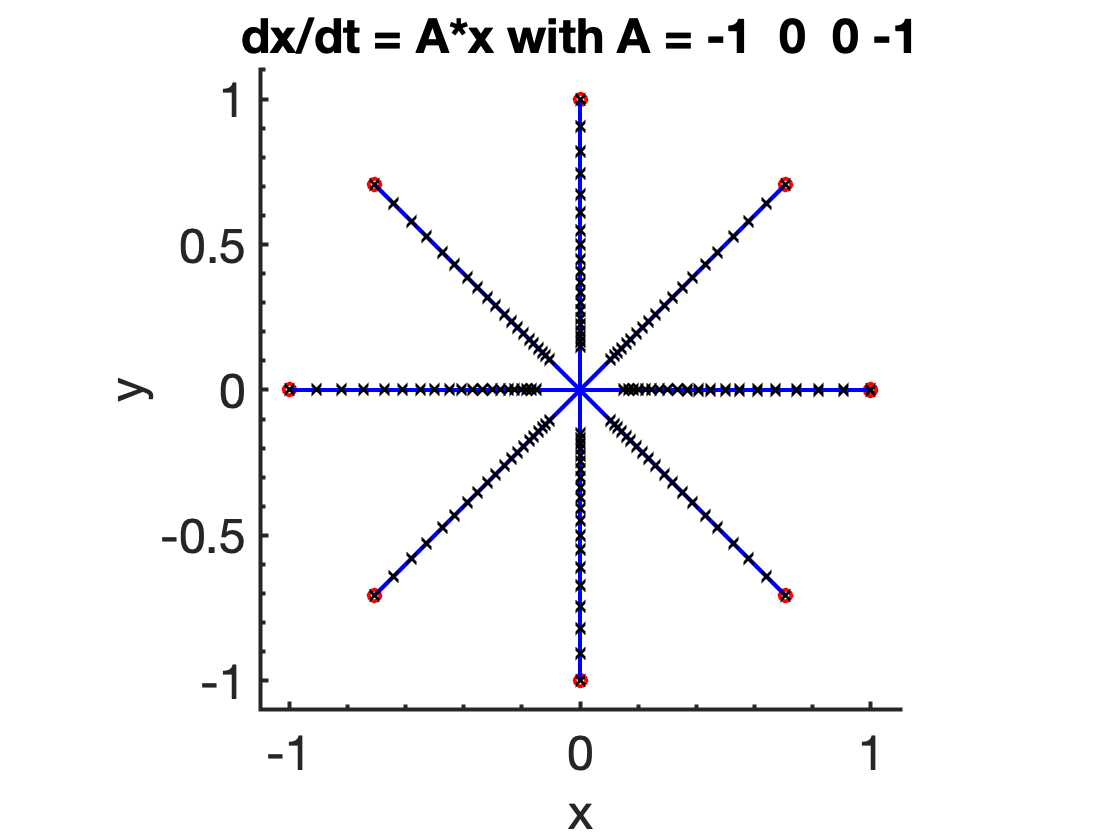

set(gca,'dataa',[1 1 1],'xlim',m1*[-1.1 1.1],'ylim',m1*[-1.1 1.1]);     %rescale the axes
PrettyFig;

## Now plot the vector field

[y1,y2]=meshgrid([-3:0.6:3],[-3:0.6:3]);
dy1dt = (A(1,1)*y1+A(1,2)*y2);
dy2dt = (A(2,1)*y1+A(2,2)*y2);

h1 = figure; 
close all;
hold on;
axis square

quiver(y1,y2,dy1dt,dy2dt,1,'color','k');

xlabel('x');
ylabel('y');
title(['Vector field with A = ' num2str(reshape(A',1,[]))]);

set(gca,'xlim',1.1*[-3 3],'ylim',1.1*[-3 3]);
PrettyFig;

## Now plot eigenvectors

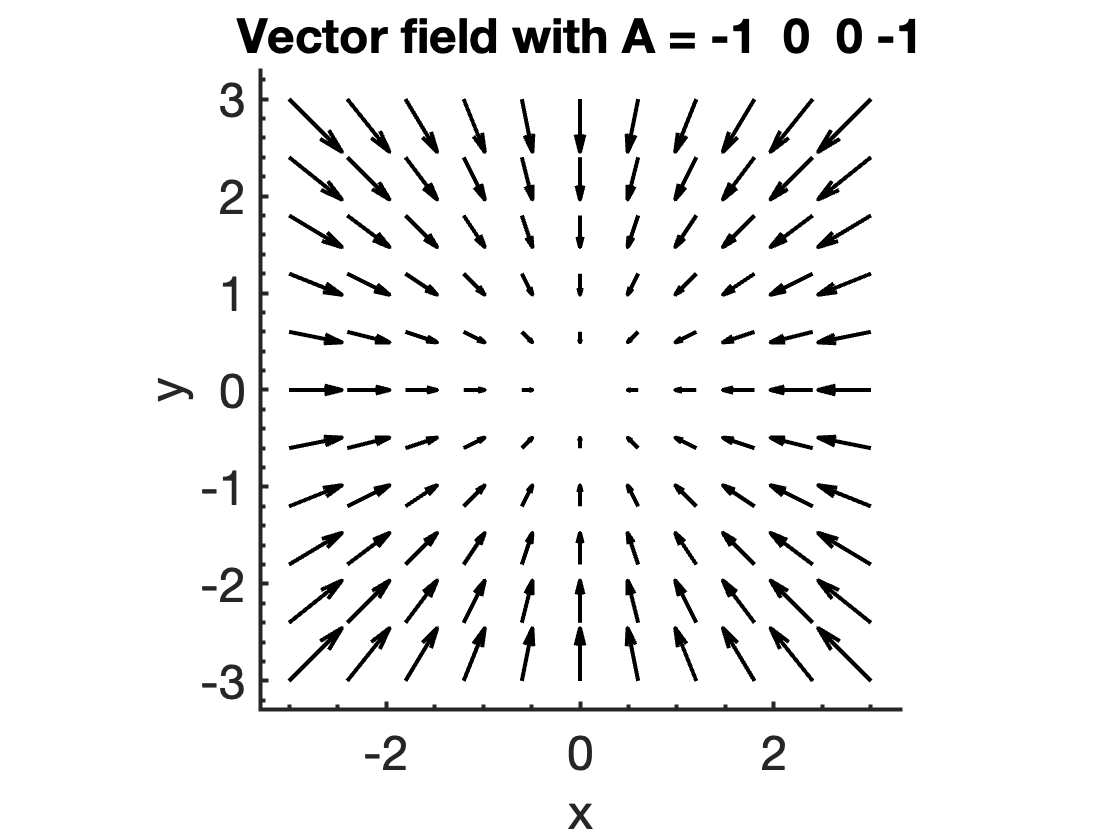

lamda1=0;lamda2=0;
if det(A)<=(trace(A)^2)/4
    lamda1=(trace(A)+sqrt(trace(A)^2-4*det(A)))/2;
    lamda2=(trace(A)-sqrt(trace(A)^2-4*det(A)))/2;
    plot([-3*A(2,1)/(lamda1-A(2,2)) 3*A(2,1)/(lamda1-A(2,2))],[-3 3],'r-');
    plot([-3*A(2,1)/(lamda2-A(2,2)) 3*A(2,1)/(lamda2-A(2,2))],[-3 3],'r-');
end
PrettyFig;